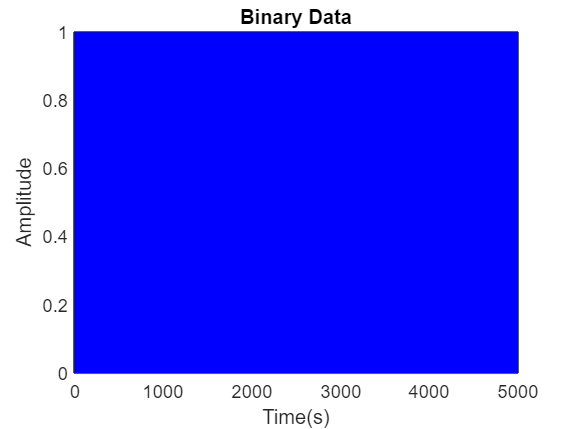

% Main Program for the PPM and PWM modulation and demodulation

% Parameters
Fs=100;            % Sampling Frequency
T=1/Fs;            % Sampling Period 
f_c=10;            % Carrier Frequency
bit_rate=2;        % Bit rate (Bits per second)
duty_cycle=0.5;    % Duty cycle for PWM
t_e=0:T:1;

% Generate random binary data
data= sin(2*pi*100*t_e);

% PPM modulation and demodulation
[ppm_modulated,ppm_demodulated]=ppm_mod_demod(data,Fs,f_c,bit_rate,T);

% PWM modulation and demodulation
[pwm_modulated,pwm_demodulated]=pwm_mod_demod(data,Fs,f_c,bit_rate,T,duty_cycle);

% Plotting
figure;

% subplot(4,1,1);
plot(data,'b-','LineWidth',2);
title('Binary Data');
xlabel('Time(s)');
ylabel('Amplitude');

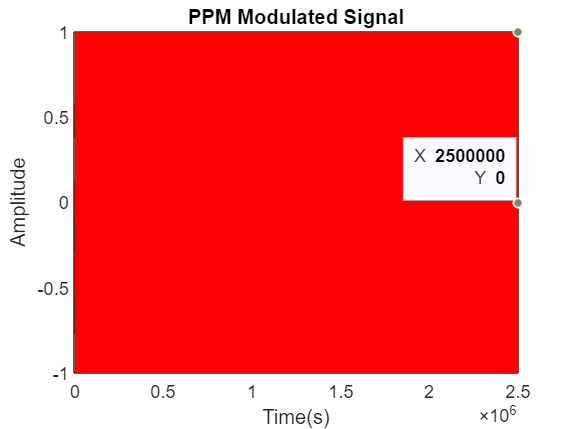


% subplot(4,1,2);
plot(ppm_modulated,'r-','LineWidth',2);
title('PPM Modulated Signal');
xlabel('Time(s)');
ylabel('Amplitude');

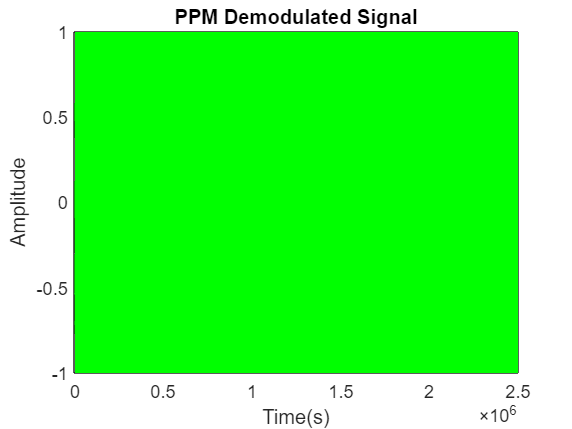


% subplot(4,1,3);
plot(ppm_demodulated,'g-','LineWidth',2);
title('PPM Demodulated Signal');
xlabel('Time(s)');
ylabel('Amplitude');

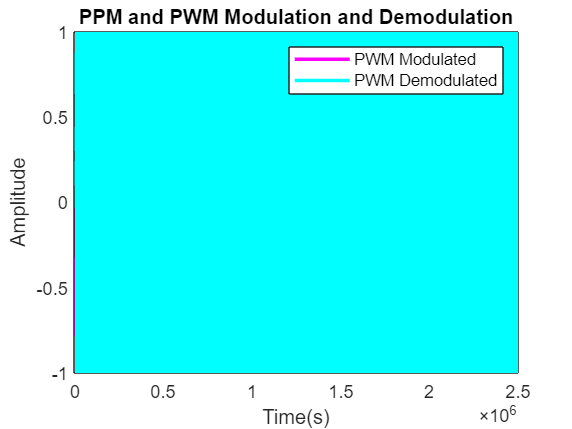


% subplot(4,1,4);
plot(pwm_modulated,'m-','LineWidth',2);
hold on;
plot(pwm_demodulated,'c-','LineWidth',2);
title('PWM Modulated and Demodulated Signals');
xlabel('Time(s)');
ylabel('Amplitude');
legend('PWM Modulated','PWM Demodulated');

% Adjusting plot layout
title('PPM and PWM Modulation and Demodulation');

function [ppm_modulated, ppm_demodulated] = ppm_mod_demod(data, Fs, f_c, bit_rate, T)
    % PPM modulation
    ppm_modulated = ppm_modulation(data, Fs, f_c, bit_rate, T);
    
    % PPM demodulation
    ppm_demodulated = ppm_demodulation(ppm_modulated, Fs, f_c, bit_rate, T);
end

function ppm_modulated = ppm_modulation(data, Fs, f_c, bit_rate, T)
    % PPM modulation
    ppm_modulated = zeros(1, length(data)*Fs/bit_rate);
    t = 0:T:(length(data)/bit_rate - T);
    
    for i = 1:length(data)
        if data(i) == 1
            ppm_modulated((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate) = cos(2*pi*f_c*t((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate));
        end
    end
end

function ppm_demodulated = ppm_demodulation(ppm_modulated, Fs, f_c, bit_rate, T)
    % PPM demodulation
    ppm_demodulated = zeros(1, length(ppm_modulated));
    t = 0:T:(length(ppm_modulated)/Fs - T);
    
    for i = 1:length(ppm_modulated)/Fs*bit_rate
        ppm_demodulated((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate) = ppm_modulated((i-1)*Fs/bit_rate + 1) * cos(2*pi*f_c*t((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate));
    end
end

function [pwm_modulated, pwm_demodulated] = pwm_mod_demod(data, Fs, f_c, bit_rate, T, duty_cycle)
    % PWM modulation
    pwm_modulated = pwm_modulation(data, Fs, f_c, bit_rate, T, duty_cycle);
    
    % PWM demodulation
    pwm_demodulated = pwm_demodulation(pwm_modulated, Fs, f_c, bit_rate, T, duty_cycle);
end

function pwm_modulated = pwm_modulation(data, Fs, f_c, bit_rate, T, duty_cycle)
    % PWM modulation
    pwm_modulated = zeros(1, length(data)*Fs/bit_rate);
    t = 0:T:(length(data)/bit_rate - T);
    
    for i = 1:length(data)
        if data(i) == 1
            pwm_modulated((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate) = square(2*pi*f_c*t((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate), duty_cycle);
        end
    end
end

function pwm_demodulated = pwm_demodulation(pwm_modulated, Fs, f_c, bit_rate, T, ~)
    % PWM demodulation
    pwm_demodulated = zeros(1, length(pwm_modulated));
    t = 0:T:(length(pwm_modulated)/Fs - T);
    
    for i = 1:length(pwm_modulated)/Fs*bit_rate
        pwm_demodulated((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate) = pwm_modulated((i-1)*Fs/bit_rate + 1) * square(2*pi*f_c*t((i-1)*Fs/bit_rate + 1:i*Fs/bit_rate));
    end
end